# BRIDGE O DOOOOM

Plotting the path

beta = 0.2

beta = 0.2000

points = linspace(0, 3.2, 1000);
x = 0.3960 * cos(2.65*(1.4 + points));
y = -0.99 * sin(1.4 + points);
syms u r t

u = beta * t

$$u = \frac{t}{5}$$

r_i = 0.3960 * cos(2.65*(1.4 + u))

$$r\_i = \frac{99\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{250}$$

r_j = -0.99 * sin(1.4 + u)

$$r\_j = -\frac{99\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{100}$$

r_k = 0 * u

$$r\_k = 0$$

assume(t,'real')
r = [r_i, r_j, r_k];
drdu = diff(r,t);
T_hat = simplify(drdu./norm(drdu))

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}} \end{array}$$


dT_hatdu=diff(T_hat,t);
N_hat=dT_hatdu/norm(dT_hatdu);
N_hat=simplify(N_hat);

vecs = transpose(linspace(0.5, 3, 3));
vecs_x = 0.3960 * cos(2.65*(1.4 + vecs));
vecs_y = -0.99 * sin(1.4 + vecs);
N = eval(subs(N_hat,vecs/beta))

N =    -0.3061    0.9520         0
    0.7310    0.6824         0
    0.3456   -0.9384         0


T = eval(subs(T_hat, vecs/beta))

T =     0.9520    0.3061         0
   -0.6824    0.7310         0
    0.9384    0.3456         0


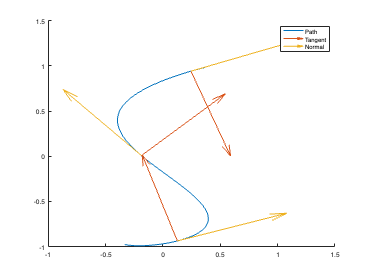

f = figure();
hold on
plot(x,y)
quiver(vecs_x, vecs_y, N(:,1), N(:, 2))
quiver(vecs_x, vecs_y, T(:,1), T(:, 2))
legend("Path","Tangent","Normal")

Plotting the velocities


vel = diff(r, t)

$$vel = \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{25000} & -\frac{99\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{500} & 0 \end{array}\right)$$

diff(T_hat)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2809\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{100\,\sqrt{\sigma_{2}}}-\frac{53\,\sigma_{3}\,\sigma_{1}}{2\,{\sigma_{2}}^{3/2}} & \frac{10\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{\sqrt{\sigma_{2}}}-\frac{25\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)\,\sigma_{1}}{{\sigma_{2}}^{3/2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)-\frac{148877\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\,\sigma_{3}}{50}\\ \sigma_{2}=2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sigma_{3}}^{2}\\ \sigma_{3}=\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right) \end{array}$$

omega = cross(T_hat, diff(T_hat))

$$omega = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{50\,\sigma_{4}\,\left(\frac{2809\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{100\,\sqrt{\sigma_{2}}}+\frac{53\,\sigma_{3}\,\sigma_{1}}{2\,{\sigma_{2}}^{3/2}}\right)}{\sqrt{\sigma_{2}}}-\frac{53\,\sigma_{3}\,\left(\frac{10\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{\sqrt{\sigma_{2}}}-\frac{25\,\sigma_{4}\,\sigma_{1}}{{\sigma_{2}}^{3/2}}\right)}{\sqrt{\sigma_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,\sigma_{4}\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)-\frac{148877\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\,\sigma_{3}}{50}\\ \sigma_{2}=2500\,{\sigma_{4}}^{2}+2809\,{\sigma_{3}}^{2}\\ \sigma_{3}=\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)\\ \sigma_{4}=\cos\left(\frac{t}{5}+\frac{7}{5}\right) \end{array}$$

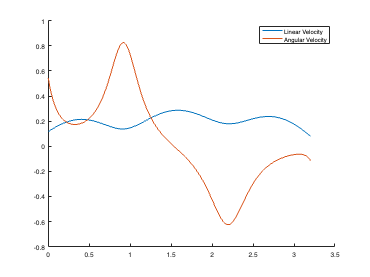

V_n = (eval(subs(vel, transpose(points)/beta)));
V_n = sqrt(sum(V_n.^2,2));
ang_vel = eval(subs(omega, transpose(points)/beta));
figure;
hold on
plot(points, V_n)
plot(points, ang_vel(:, 3))
legend("Linear Velocity", "Angular Velocity")

Left Right Velocities

V_L = V_n - ang_vel(:, 3) * 0.245/2

V_L =     0.0512
    0.0540
    0.0567
    0.0594
    0.0621
    0.0647
    0.0672
    0.0698
    0.0722
    0.0747


V_R = V_n + ang_vel(:, 3) * 0.245/2

V_R =     0.1846
    0.1843
    0.1841
    0.1839
    0.1838
    0.1837
    0.1837
    0.1837
    0.1837
    0.1838
